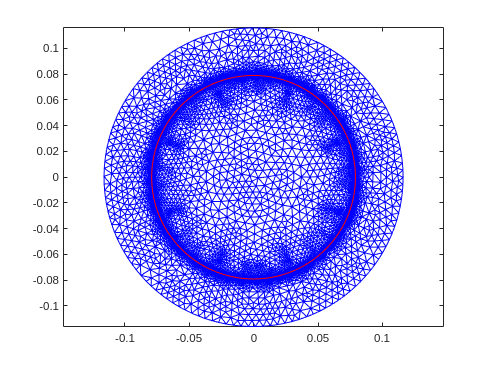

% this script doubles the points on the interface beteen stator and rotor
% (in the air gap) and creates also two edge lists (eI1, eI2), one belonging to the stator
% and the other belonging to the rotor.

load -mat motor.mat
% edge index 644 is the outer circle of the inner two circles of the air
% gap
interface_ind = 644;
t = double(t);
e = double(e);
% [p,e,t] = refinemesh(p,e,t,zeros(length(p),1));
pdemesh(p,e(:,e(3,:)==interface_ind),t)


e_dupl = e(:,e(3,:)==interface_ind);
p_ind = unique(e_dupl(1:2,:))';

np = size(p,2); np_ind = length(p_ind);
p = [p,p(:,p_ind)]; %add additional points on the interface

p_ind_new = (np+1):(np+np_ind);
for i = 1:size(e_dupl,2)
    e_i = e_dupl(:,i);
    e_dupl(1,i) = p_ind_new(p_ind==e_i(1));
    e_dupl(2,i) = p_ind_new(p_ind==e_i(2));
end

air_gap = find(matches(regions_2d,'air_gap'));
air_gap_stator = find(matches(regions_2d,'air_gap_stator'));

% change corresponding node indices of the triangles of the air gap stator
t_statorair = t(:,t(4,:)==air_gap_stator);
for i = 1:size(t_statorair,2)
    t_i = t_statorair(:,i);
    p_ind1 = p_ind==t_i(1);
    p_ind2 = p_ind==t_i(2);
    p_ind3 = p_ind==t_i(3);
    if any(p_ind1)
        t_statorair(1,i) = p_ind_new(p_ind==t_i(1));
    end
    if any(p_ind2)
        t_statorair(2,i) = p_ind_new(p_ind==t_i(2));
    end
    if any(p_ind3)
        t_statorair(3,i) = p_ind_new(p_ind==t_i(3));
    end
end
t(:,t(4,:)==air_gap_stator) = t_statorair;

eI1 = e(:,e(3,:)==interface_ind);
eI2 = e_dupl;
t1 = t(:,t(4,:)==air_gap);
t2 = t(:,t(4,:)==air_gap_stator);
tInd1 = find(t(4,:)==air_gap); tInd2 = find(t(4,:)==air_gap_stator); 
neI1 = size(eI1,2); neI2 = size(eI2,2);
nt1 = size(t1,2); nt2 = size(t2,2);

% find triangles belonging to the edges
for i = 1:neI1
    for j = 1:nt1
        t_j = t1(:,j);
        if all(ismember(eI1(1:2,i),t_j(1:3)))
            eI1(4,i) = tInd1(j);
            break
        end
    end
end
for i = 1:neI2
    for j = 1:nt2
        t_j = t2(:,j);
        if all(ismember(eI2(1:2,i),t_j(1:3)))
            eI2(4,i) = tInd2(j);
            break
        end
    end
end


save DataPreCalculation/motor_divided.mat p e t eI1 eI2 regions_1d regions_2d j3 m

### Additional code (was needed for setting up the code above):

pdemesh(p,[],t(:,t(4,:)==air_gap_stator), 'EdgeColor','r')
hold on
pdemesh(p,[],t(:,t(4,:)==air_gap), 'EdgeColor','b')
pdemesh(p,[],t(:,t(4,:)==149), 'EdgeColor','y')
hold off

pdemesh(p,e_dupl,t)

%% finding points of rotor
magnet_ind = find(contains(regions_2d,'magnet'));
rotorParts_ind = find(contains(regions_2d,'rotor'));
air_gap_ind = find(matches(regions_2d,'air_gap'));
shaft_ind = find(contains(regions_2d,'shaft'));
rotor_ind = [magnet_ind,rotorParts_ind,air_gap_ind,shaft_ind];

t_ind = ismember(t(4,:),rotor_ind);
t_rotor = t(:,t_ind);
p_rotor_ind = unique(t_rotor(1:3,:));
p_rotor_ref = p(:,p_rotor_ind);
M_vec_ref = M_vec;
angle = 2*pi/128;
Rot = [cos(angle), -sin(angle); sin(angle), cos(angle)];
p(:,p_rotor_ind) = Rot*p_rotor_ref;

eI = calcEdgeInterfaceCircle(p,eI1,eI2,t);

Elapsed time is 0.035541 seconds.


i = 13;
tr1 = eI(3,i);
tr2 = eI(4,i);
pdemesh(p,[],t(:,[tr1, tr2]))
hold on
pos = p(:,t(eI(5,i),tr1))
plot(pos(1),pos(2),'r+')
pos = p(:,t(eI(6,i),tr2))
plot(pos(1),pos(2),'r*')
hold off

i=i+1;
p1 = p(:,eI(1,i));                         % First Point
p2 = p(:,eI(2,i));                          % Second Point
dp = p2-p1;                         % Difference
figure
quiver(p1(1),p1(2),dp(1),dp(2),0)